# Sistemas de Control II - FCEFyN (UNC)

## Caso de estudio 2 - Motor (Actividad 1.5)

clear all; close all; clc;

data= readtable('../Resources/Curvas_Medidas_Motor_2025_v.xls');
data;
% Convert table to array. Apply transpose.
dataT= table2array(data);

% Obtain time(t).
t  = dataT(:,1);
wr = dataT(:,2);
ia = dataT(:,3);
v  = dataT(:,4);

Plot measurements

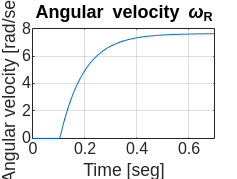

figure(1); plot(t, wr); title('Angular velocity \omega_{R}'); 
ylabel('Angular velocity [rad/seg]'); xlabel('Time [seg]');
grid on; xlim([0, 0.7]);

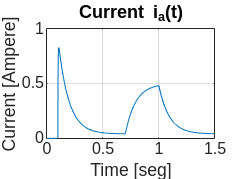

figure(2); plot(t, ia); title('Current i_{a}(t)'); 
ylabel('Current [Ampere]'); xlabel('Time [seg]');
grid on;

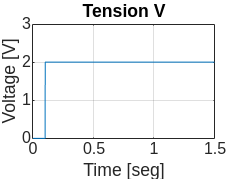

figure(3); plot(t, v); title('Tension V'); 
ylabel('Voltage [V]'); xlabel('Time [seg]');
grid on; ylim([0, 3])

Apply Chen Method to $$ Angular \, velocity \, (\omega_{R}) $$

K= max(wr)

K = 7.6247


i  = 205;
h  = 30;

t1 = t(i);
y1 = wr(i)

y1 = 5.0885

t2 = t(i+h);
y2 = wr(i+h);
t3 = t(i+2*h);
y3 = wr(i+2*h);

% k1, k2, k3 calculate.
k1 = (y1/K)-1;
k2 = (y2/K)-1;
k3 = (y3/K)-1;

ans = 5.0885